# Voxelwise maps using flexible linear mixed effects models

This live script walks through fitlme_voxelwise, which fits a linear mixed effects model at each voxel using a metadata table and a fitlme model specification.

## Overview of fitlme_voxelwise

The function uses fmri_data or image_vector objects and a MATLAB table with one row per observation. You provide either a Wilkinson formula string or a role table, and fitlme_voxelwise builds and fits the mixed effects model at every voxel, returning beta and t maps.

The metadata table is central: variables are referenced by name in the formula (for example, temperature and subject_id). This means you can use the full mixed effects syntax that fitlme supports, including random intercepts and random slopes defined in terms of table variables.

Degrees of freedom (DFE) should be corrected for mixed effects models (for example, the Satterthwaite approximation). DFE should usually be close to the number of subjects, not the total number of observations, because the effective sample size is determined by the grouping structure.

## Worked example: BMRK3 pain dataset

Load the example dataset and create the metadata table.

% Load the example dataset
fmri_data_file = which('bmrk3_6levels_pain_dataset.mat');
load(fmri_data_file)

% Create metadata_table with one row per image
% Each row holds subject_id and temperature for that observation
t = table(image_obj.additional_info.subject_id, image_obj.additional_info.temperatures, ...
    'VariableNames', {'subject_id', 'temperature'});

image_obj.metadata_table = t;

Run voxelwise mixed effects model and extract the temperature effect.

% Fit a random intercept and random slope model for temperature
out = fitlme_voxelwise(image_obj, image_obj.metadata_table, ...
    'Y ~ 1 + temperature + (1 + temperature | subject_id)', 0.005, 'unc');

% Extract the temperature t-map (second fixed effect) and visualize
% The montage below should resemble the reference image that follows
t_obj_temp_fitlme = get_wh_image(out.t, 2);
create_figure; axis off; montage(t_obj_temp_fitlme, 'onerow');

Reference output for the mixed effects temperature t-map:

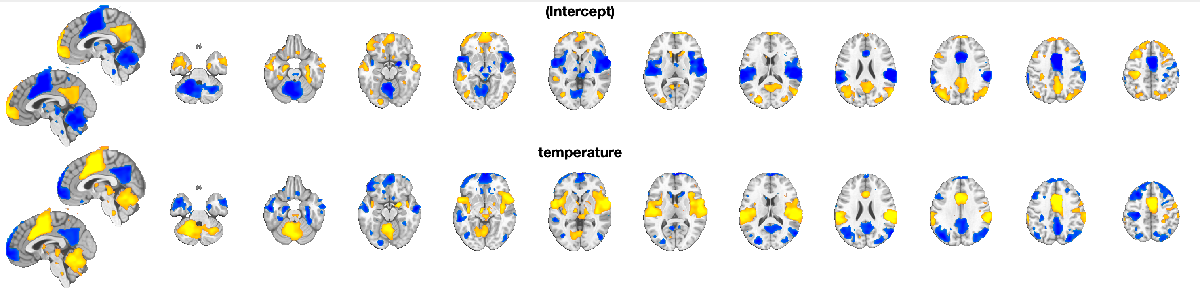

## Two-stage summary statistics (2SSS)

The two-stage summary statistics approach first builds within-person contrasts, then runs a second-level test across subjects. Here, we create a linear temperature contrast for each subject and then run a one-sample t-test across those subject-level contrasts.

% Build within-person contrasts across the six temperature levels
C = [-5 -3 -1 1 3 5]';
C_subj = repmat({C}, 1, 33);
C_subj_matrix = blkdiag(C_subj{:});

% Apply the contrast to get one image per subject
contrast_dat = image_obj.dat * C_subj_matrix;
contrast_obj = image_obj;
contrast_obj.dat = contrast_dat;
contrast_obj.removed_images = false(33, 1);
contrast_obj.dat_descrip = '.dat contains one linear contrast across temperatures for each of 33 subjects';

% Run the 2SSS approach and threshold the t-map
% The montage below should resemble the mixed effects map in overall structure
% but can differ in effect size due to different degrees of freedom
t_obj_temp_2sss = ttest(contrast_obj);
t_obj_temp_2sss = threshold(t_obj_temp_2sss, 0.005, 'unc');
create_figure; axis off; montage(t_obj_temp_2sss, 'onerow');

## Comparing fitlme and 2SSS

The comparison below plots t-values from the 2SSS map versus the fitlme map. Green points indicate voxels that are significant in both maps but show a higher magnitude t-value for the 2SSS approach (positive or negative). This illustrates that the two analyses capture similar effects, and the summary statistics approach can be more powerful when subjects are estimated with similar precision.

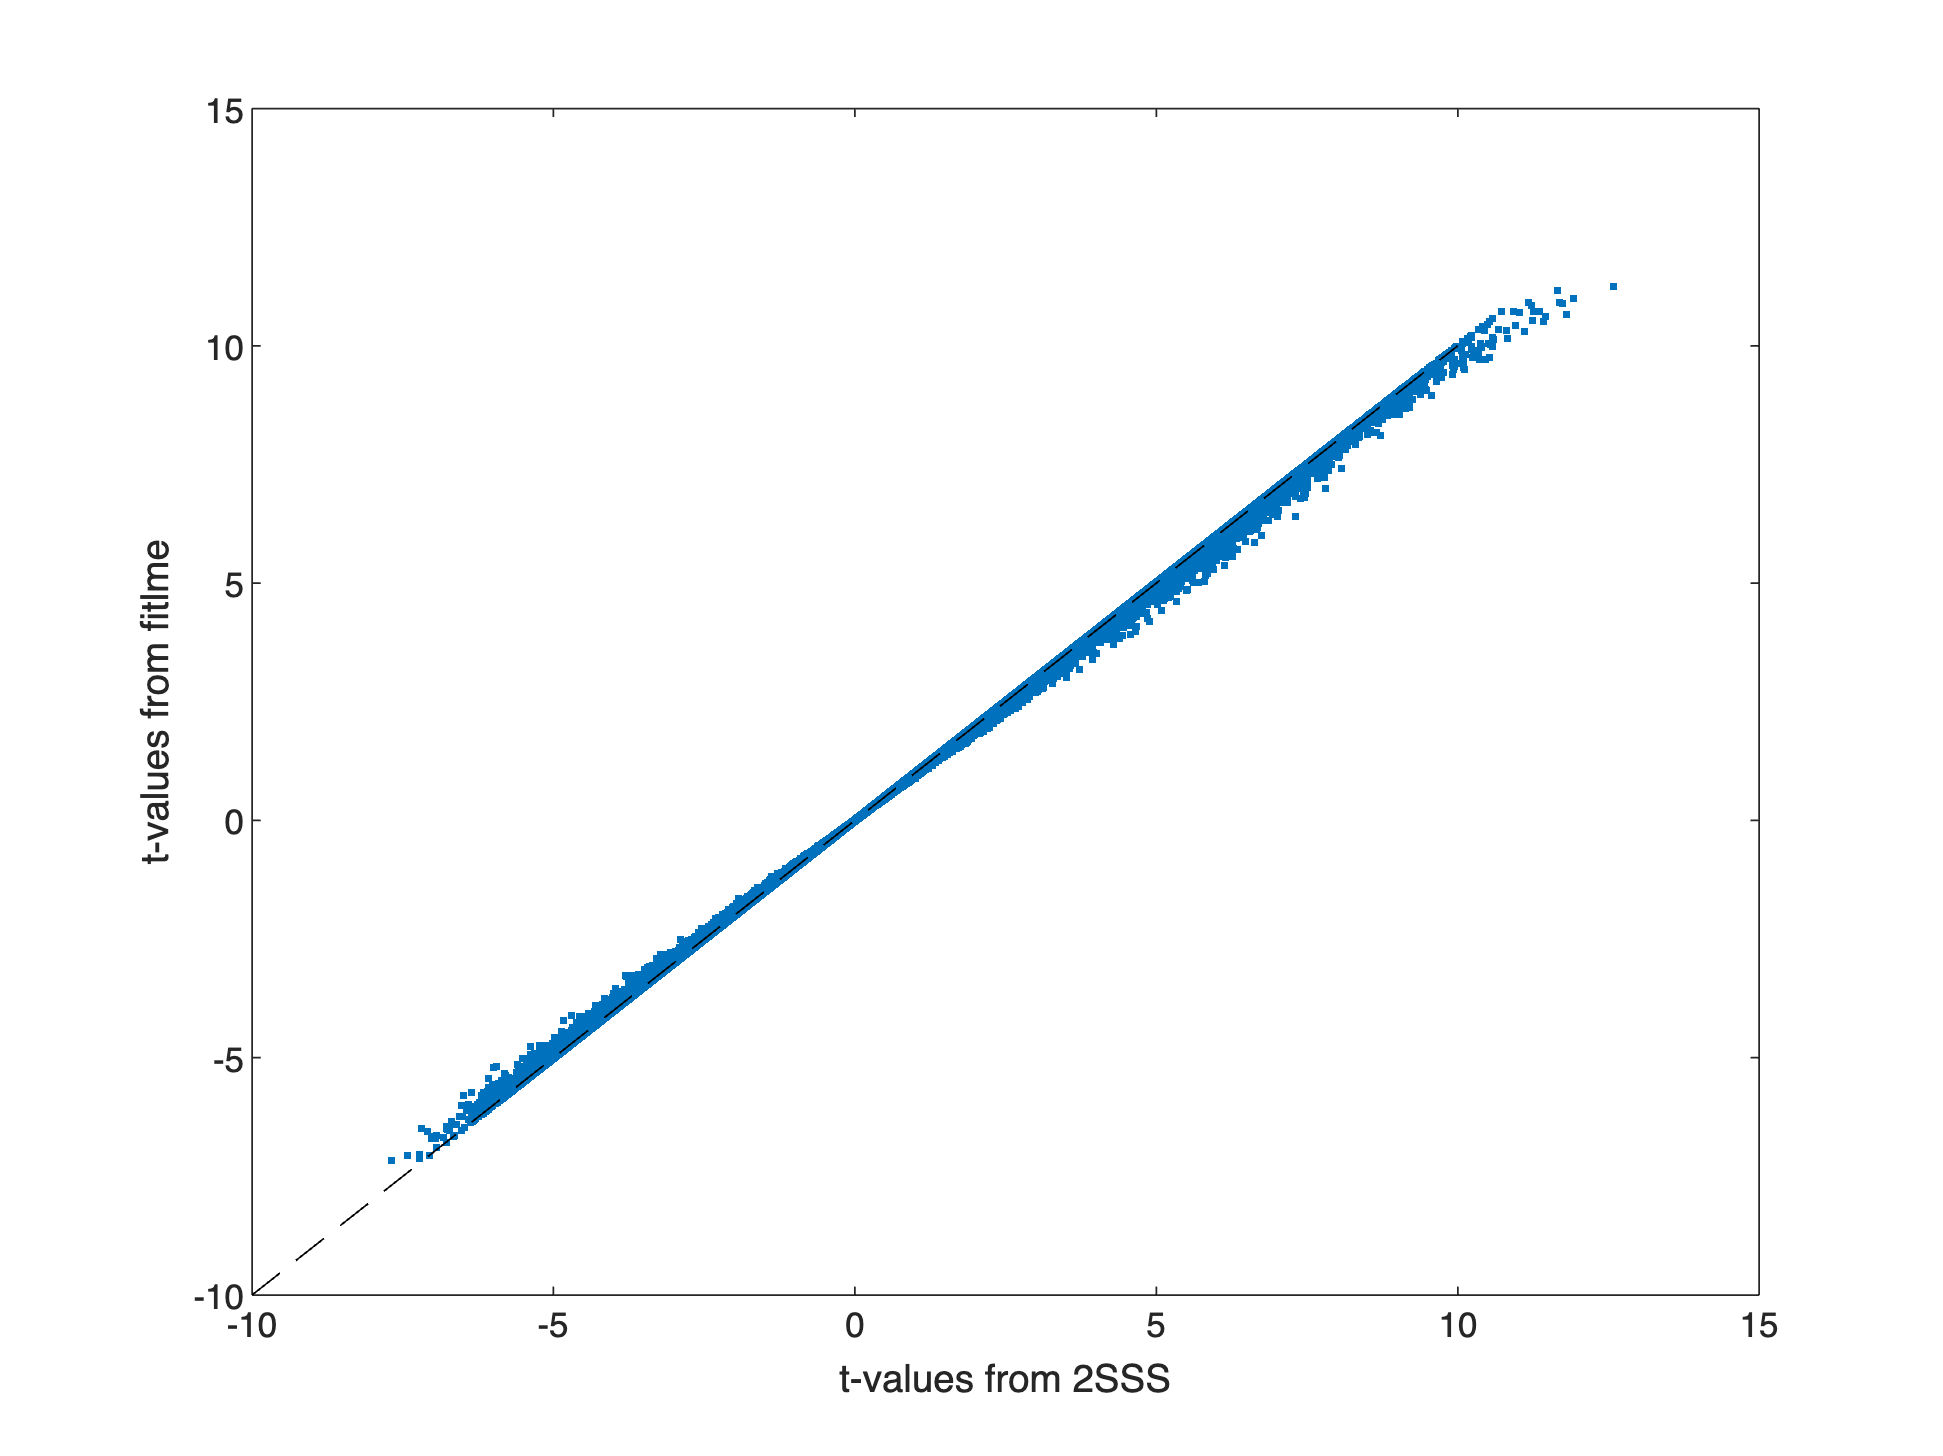

% Compare the t-maps in a scatterplot
figure; plot(t_obj_temp_2sss.dat, t_obj_temp_fitlme.dat, '.');
hold on; plot([-10 10], [-10 10], '--', 'Color', 'k');
xlabel('t-values from 2SSS'); ylabel('t-values from fitlme');

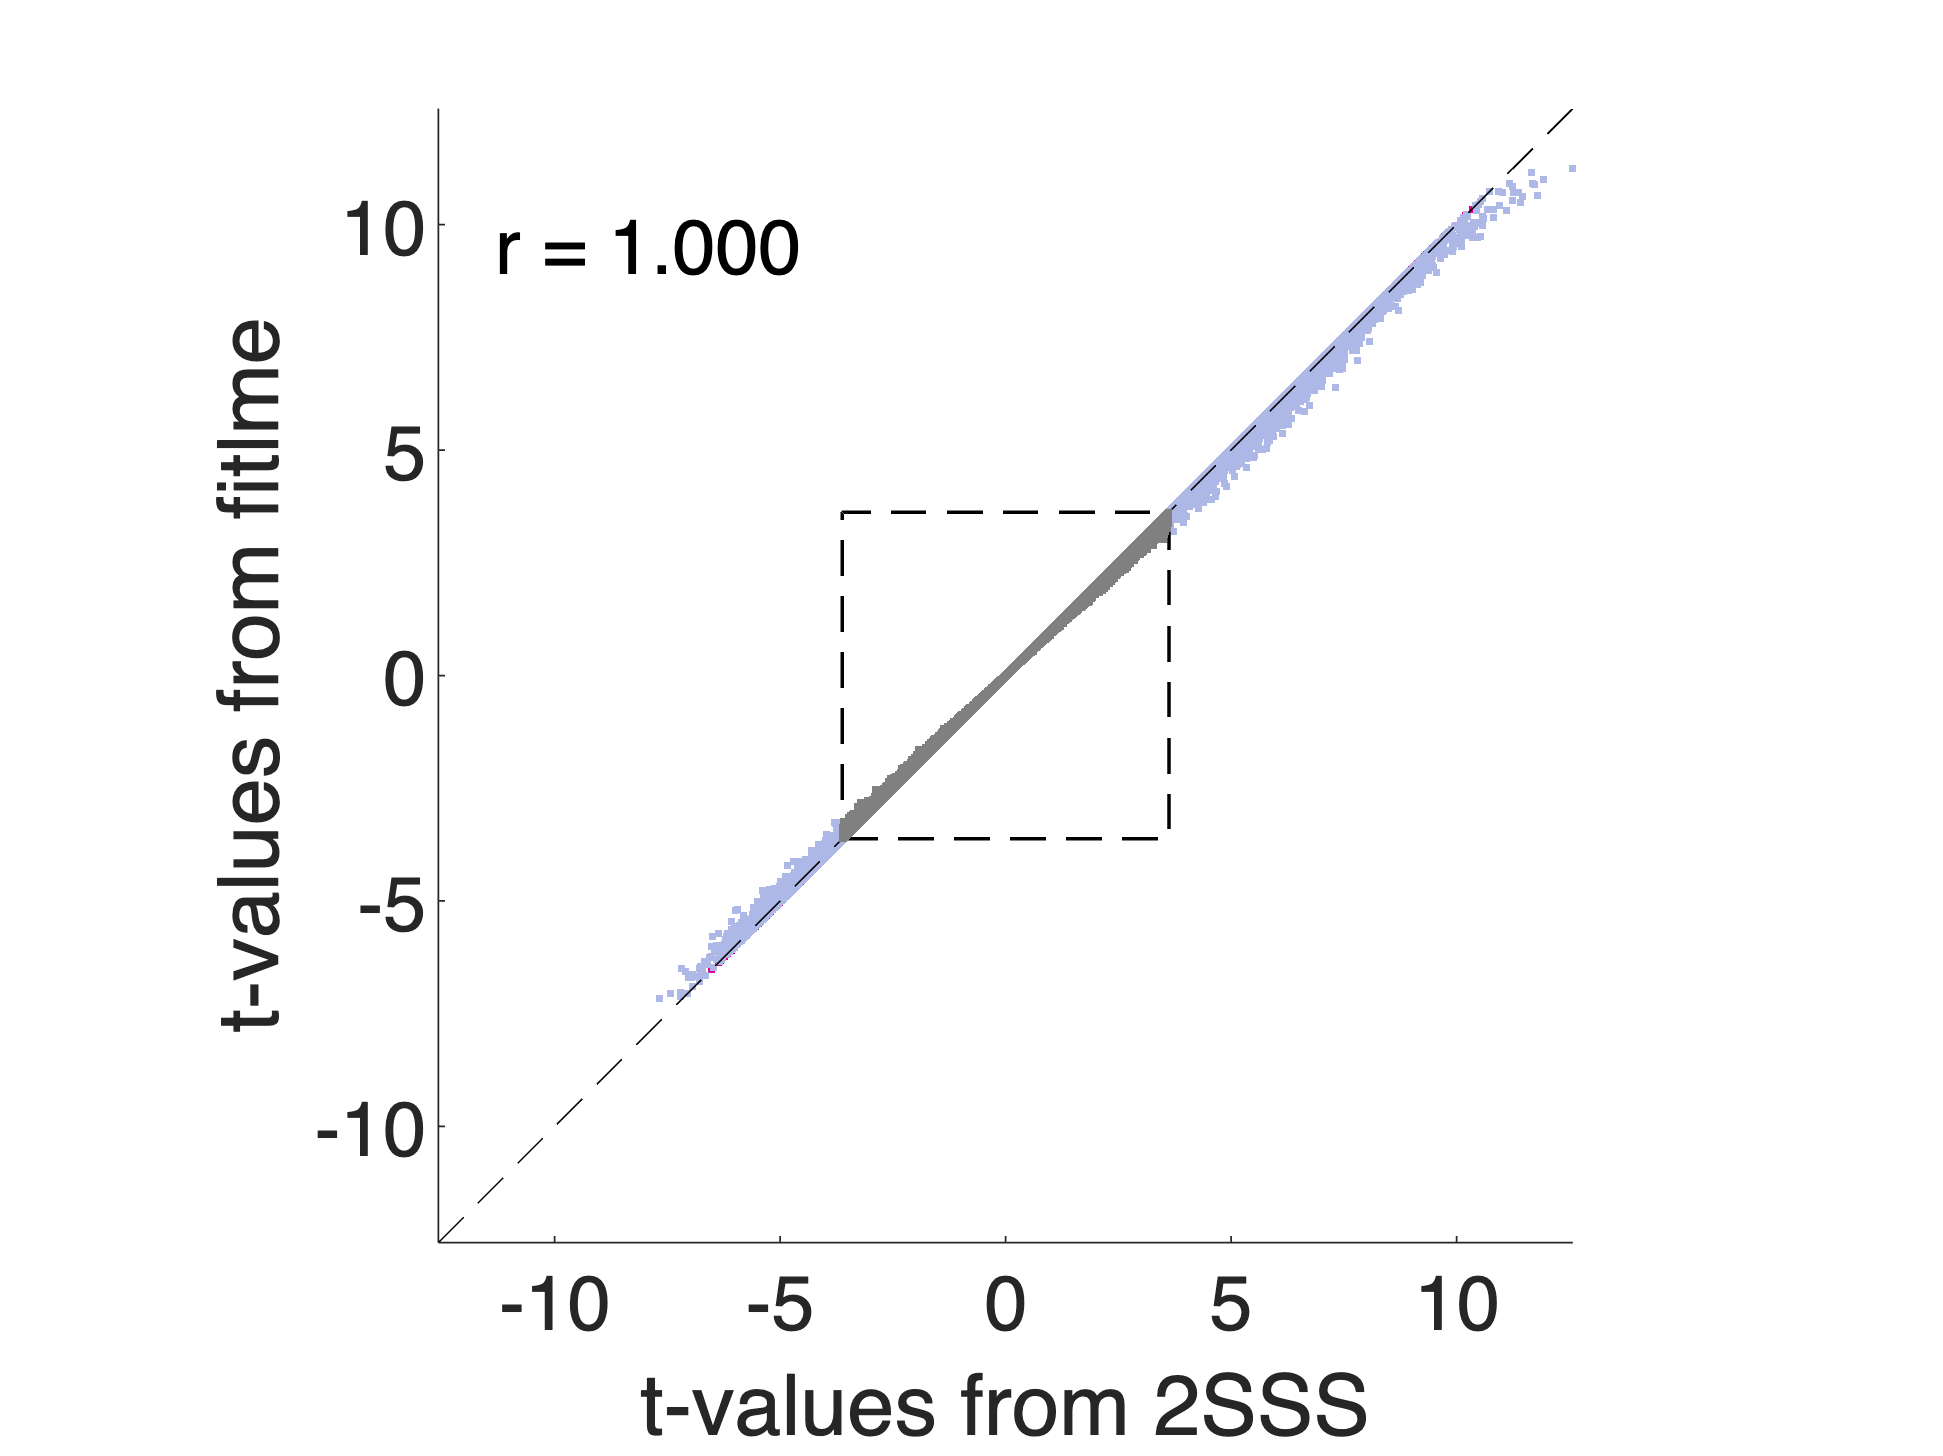


% Alternate visualization with color-coded significance
h = image_scatterplot(t_obj_temp_2sss, t_obj_temp_fitlme, ...
     'pvaluebox', 0.001, 'colorpoints');
xlabel('t-values from 2SSS'); ylabel('t-values from fitlme');

### Bonus: Compare t-values before and after normalization by CSF/WM 

[image_obj_norm, statstab] = normalize_gm_by_wm_csf(image_obj);

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
iimg_get_data: loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.023980 seconds.
Number of unique values in dataset: 19483  Bit rate: 14.25 bits
Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
iimg_get_data: loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.025774 seconds.
Number of unique values in dataset: 438  Bit rate: 8.77 bits

contrast_dat = image_obj_norm.dat * C_subj_matrix;
contrast_obj = image_obj_norm;
contrast_obj.dat = contrast_dat;

t_obj_temp_2sss_norm = ttest(contrast_obj);

One-sample t-test
Calculating t-statistics and p-values


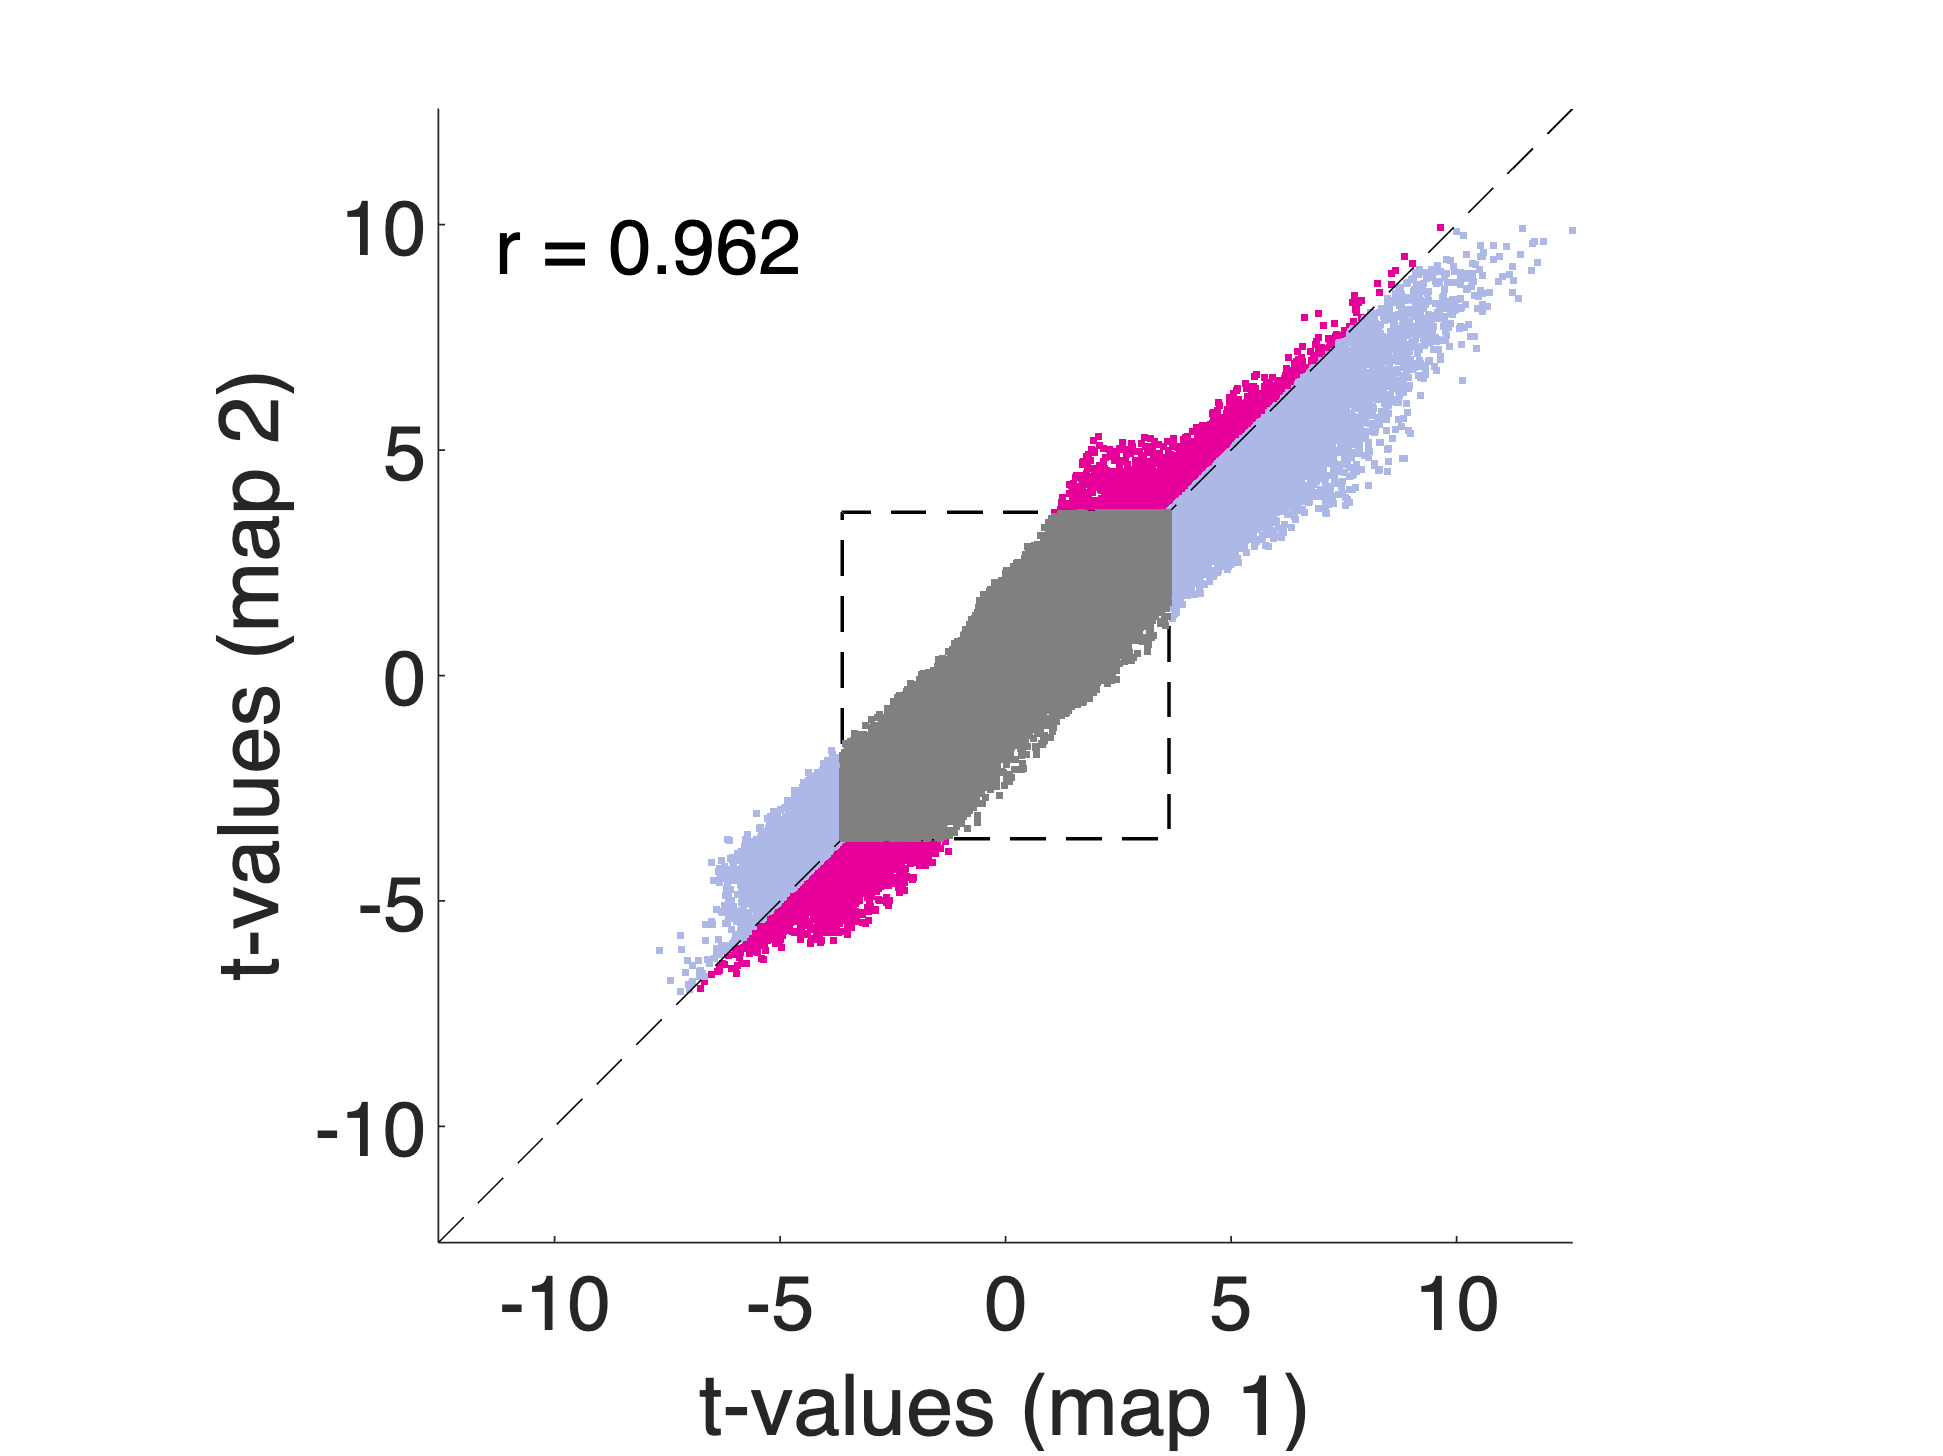


% make voxel list match
t_obj_temp_2sss_norm = remove_empty(t_obj_temp_2sss_norm, t_obj_temp_2sss.removed_voxels);

h = image_scatterplot(t_obj_temp_2sss, t_obj_temp_2sss_norm, 'pvaluebox', 0.001, 'colorpoints');